clc
clear

disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param.ctrl.T_ref = util.Celsius2Kelvin(20);

T_kelvin = 293.1500

param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


param = model.calculateWDelta(param,0);
simtime = 10*60;




## Control

% param = control.DesignProcedure1(param,0); 
% param = control.DesignProcedure2(param,0,0);
param = control.DesignProcedureWeight(param,0,1);

Evaluation of design procedure 2 
Q is positive definite


ans =     0.0492    0.0496    0.0511    0.0519    0.1515    0.1524    0.1570    0.1585    0.5393    0.5393    0.5393    0.5393    1.1006    1.1015    1.1114    1.1127


Gamma is found to be:


ans = 1

Eigenvalues of the decoupled systems are all negative 


ans =   -4.2521 + 0.0000i  -0.2987 + 0.1886i  -0.2987 - 0.1886i  -4.3133 + 0.0000i  -0.3152 + 0.1995i  -0.3152 - 0.1995i  -4.2779 + 0.0000i  -0.3217 + 0.2003i  -0.3217 - 0.2003i  -4.2622 + 0.0000i  -0.3105 + 0.1861i  -0.3105 - 0.1861i


Eigenvalues of the coupled systems are all negative 


ans =    -4.5181   -4.6724   -4.7900   -4.8171   -0.9207   -1.0037   -1.0502   -0.6866   -0.3243   -0.2914   -0.2778   -0.2817


0.000000, 0.000000, 0.000000, -89.839659, 
-23.728742, 0.000000, -60.282624, -60.282624, 
0.000000, -0.279473, -0.279473, -0.279473, 


0.000000, 0.000000, -0.912699, -0.000000, 
0.000000, 0.000000, -1.070881, -0.000000, 


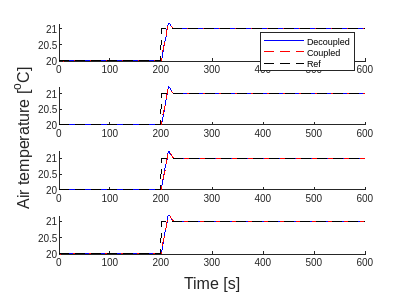

ans = 1×4 struct array with fields:
    time
    Tw
    Ta
    T


% param = control.DesignProcedureRealUncertainties(param,1,{[-0.1,0.1],[-0.1,0.1],[-0.1,.1],[-0.1,.1]});
% param= control.DesignProcedureRealUncertainties(param,1,{[-1,1]});


util.SimulateStep(param,"ExaminatinWightedDesignProedureStepGamma1",0)

## Structured uncertainties

s = tf('s');

w = 1;
M = model.calculateM(param)

s =
 
  s
 
Continuous-time transfer function.
Model Properties

M =
 
  From input 1 to output...
           -1.743 s^47 - 160.1 s^46 - 7046 s^45 - 1.978e05 s^44 - 3.978e06 s^43 - 6.108e07 s^42 - 7.45e08 s^41 - 7.412e09 s^40 - 6.133e10 s^39 - 4.282e11 s^38 - 2.551e12 s^37 - 1.308e13 s^36 - 5.809e13 s^35 - 2.25e14 s^34 - 7.631e14 s^33 - 2.276e15 s^32 - 5.987e15 s^31 - 1.394e16 s^30 - 2.876e16 s^29 - 5.275e16 s^28 - 8.613e16 s^27 - 1.254e17 s^26 - 1

hinfnorm(M)

ans = 1.1114

max(max(sigma(M)))

ans = 1.1110

W = logspace(-1,3,400);
SV = sigma(M, W)

SV =     1.0307    1.0319    1.0332    1.0345    1.0358    1.0372    1.0386    1.0401    1.0416    1.0432    1.0447    1.0464    1.0480    1.0497    1.0515    1.0533    1.0551    1.0569    1.0588    1.0607    1.0626    1.0646    1.0665    1.0685    1.0705    1.0726    1.0746    1.0766    1.0786    1.0807    1.0827    1.0847    1.0867    1.0886    1.0905    1.0924    1.0942    1.0960    1.0977    1.0994    1.1009    1.1024    1.1038    1.1052    1.1064    1.1075    1.1084    1.1093    1.1100    1.1106
    1.0233    1.0242    1.0252    1.0262    1.0272    1.0282    1.0292    1.0303    1.0314    1.0326    1.0337    1.0349    1.0361    1.0373    1.0386    1.0399    1.0412    1.0425    1.0438    1.0452    1.0465    1.0479    1.0493    1.0507    1.0521    1.0535    1.0549    1.0562    1.0576    1.0590    1.0603    1.0617    1.0630    1.0642    1.0655    1.0667    1.0679    1.0690    1.0701    1.0712    1.0722    1.0732    1.0741    1.0750    1.0758    1.0765    1.0772    1.0778    1.0783    

spectral = zeros(1,length(W));
Ms = freqresp(M,W);
for i=1:length(W)   
    spectral(i) = abs(eigs(Ms(:,:,i),1));
end

[bounds,muinfo]  = mussv(frd(M,W),[4,0],'an');

Points completed: 400/400


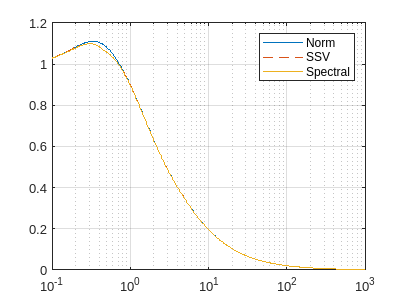


[VDelta,VSigma,VLmi] = mussvextract(muinfo);
VDelta.responsedata(:,:,:);
upperBound = bounds(1).ResponseData(:);

figure()
semilogx(W,max(SV),W,upperBound,'--',W,spectral)
% ylim([0;4])
legend('Norm', 'SSV', 'Spectral')
grid on

set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 16 9]);
% saveas(gcf,'../Images/SSV_PLOT_Procedure2','epsc')

% H = [An, B*B'; -(K*eye(12))'*(K*eye(12)), -An']

% W = logspace(-1,3,100);
% Ms = freqresp(Mn2,W);
% yalmip('clear')
% gamma = 0.01;
% % D = sdpvar(4,4,'symmetric','complex');
% % Q = D*D'
% D = sdpvar(4,4,'toeplitz','complex');
% Q = D-diag(imag(diag(D)))*sqrt(-1)
% constraints = [Ms(40)*Q*Ms(40)' <= gamma^2*Q, Q>=0]
% options = sdpsettings('verbose',0,'solver','mosek');
% sol = optimize(constraints,[],options)
% value(Q)
% eig(value(Q))

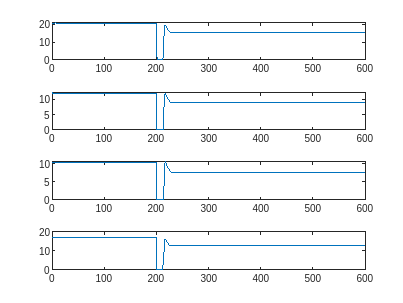

figure()
tiledlayout('vertical')
for i=1:4
    x0 = [param.ctrl.T_wOP(i); param.ctrl.T_aOP(i); 0];
    [t,x] = ode23s(@(t,x)model.decoupledDynamics(t,x,i,param,200),[0 simtime],x0);
    decoupledResults(i).time = t;
    decoupledResults(i).Tw = x(:,1);
    decoupledResults(i).Ta = x(:,2);
    decoupledResults(i).T = x(:,3);

    q = zeros(1,length(t));
      for k=1:length(t)
        [~,q(k)] = model.decoupledDynamics(t(k),x(k,:)',i,param);
      end
      nexttile
      plot(t,q*3600)
end

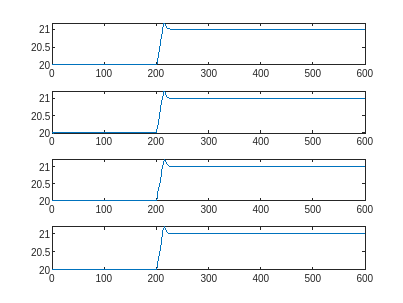



figure()
tiledlayout('vertical')
for i=1:4
    nexttile
    plot(decoupledResults(i).time,decoupledResults(i).Ta-273.15)
end

x0 = [param.ctrl.T_wOP.'; param.ctrl.T_aOP.'; zeros(4,1)];
% options = odeset('RelTol',1e-8,'AbsTol',1e-10);
[t,x] = ode23s(@(t,x)model.coupledDynamics(t,x,param,200),[0 simtime],x0);

0.000000, 0.000000, 0.000000, -89.839659, 
-23.728742, 0.000000, -60.282624, -60.282624, 
0.000000, -0.279473, -0.279473, -0.279473, 


0.000000, 0.000000, -0.912699, -0.000000, 
0.000000, 0.000000, -1.070881, -0.000000, 


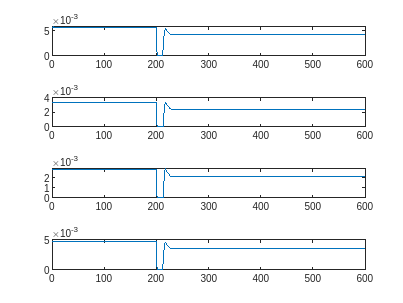

coupledResults.time = t;
coupledResults.Tw = x(:,1:4);
coupledResults.Ta = x(:,5:8);
coupledResults.T = x(:,9:12);

q = zeros(4,length(x(:,1)));
for k=1:length(x(:,1))
  [~,q(:,k)] = model.coupledDynamics(t(k),x(k,:)',param);
end
figure()
tiledlayout('vertical')
for i=1:4
    nexttile
    plot(t,q(i,:));
end

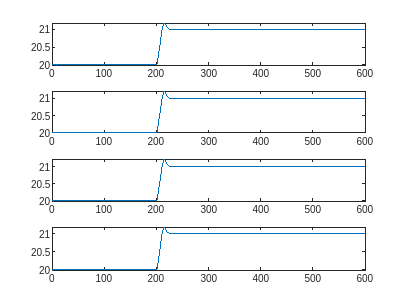



figure()
tiledlayout('vertical')

for i=1:4
    nexttile
    plot(coupledResults.time,coupledResults.Ta(:,i)-273.15)
end

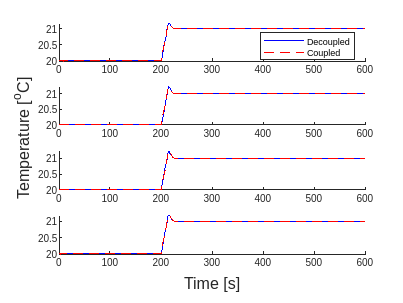

figure()
f = tiledlayout('vertical');
for i=1:4
    nexttile
    hold on
    plot(decoupledResults(i).time,decoupledResults(i).Ta-273.15,'blue')
    plot(coupledResults.time,coupledResults.Ta(:,i)-273.15,['red','--'])
    if i==1
        legend('Decoupled','Coupled',Location='northeast')
    end
    hold off
end
xlabel(f,'Time [s]')
ylabel(f,'Temperature [^{o}C]')